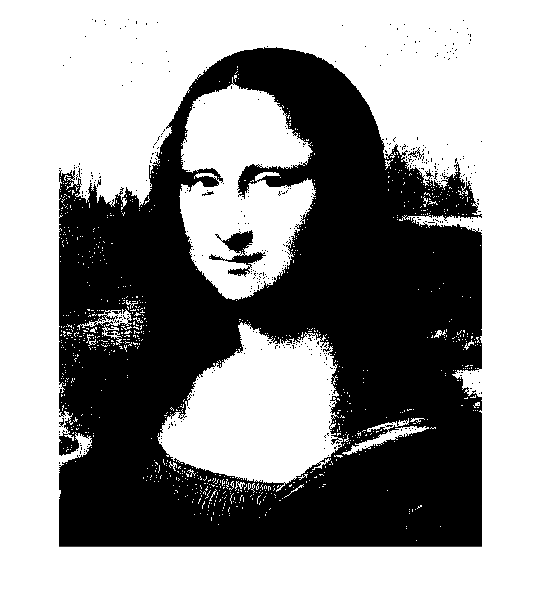

clc
clear

% Add paths
addpath("util");

% settings
scale = 1.0;

%Load image
image = im2double(imread("images/Mona_Lisa.jpg"));
image = imresize(image, scale);
%imshow(image);

% "Segment" image
gray = im2gray(image);
thresh = (gray >= 0.4);

% Filter segmentation
%SE = strel("disk", 1, 8);
%thresh = imerode(thresh, SE);
%thresh = imdilate(thresh, SE);


imshow(thresh);

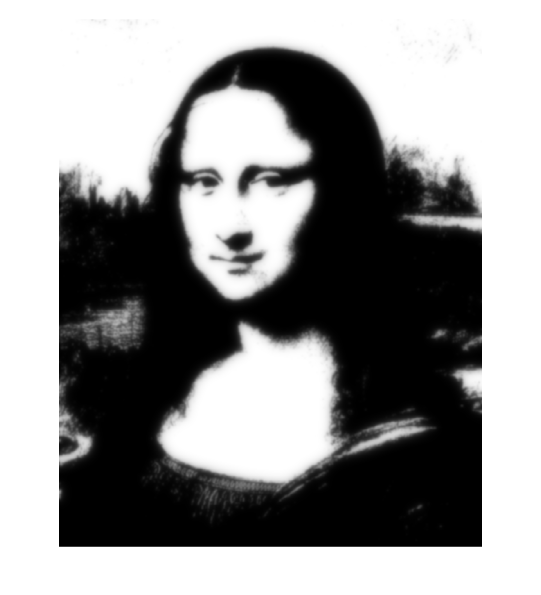



gauss1 = imgaussfilt(im2gray(im2double(thresh)), 4*scale);
gauss2 = imgaussfilt(im2gray(im2double(thresh)), 8*scale);
gauss3 = imgaussfilt(im2gray(im2double(thresh)), 16*scale);
gauss4 = imgaussfilt(im2gray(im2double(thresh)), 32*scale);

%imshow(gauss1);
%imshow(gauss2);
%imshow(gauss3);
%imshow(gauss4);

gauss_combined = (1/4)*(gauss1 + gauss2 + gauss3 + gauss4);
%gauss_combined = im2gray(im2double(thresh));
imshow(gauss_combined);


% Multiply heightmaps

% Load diffure
grass_diffuse = im2double(imread("textures/Bricks075A_1K-PNG/Bricks075A_1K_Color.png"));
stone_diffuse = im2double(imread("textures/Grass004_1K-PNG/Grass004_1K_Color.png"));

grass_diffuse = imresize(grass_diffuse, scale);
stone_diffuse = imresize(stone_diffuse, scale);

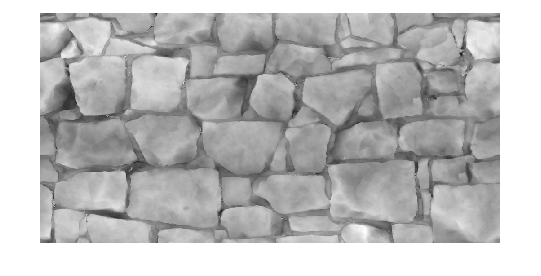

% Load Heightmap
grass_displace = im2double(imread("textures/Bricks075A_1K-PNG/Bricks075A_1K_Displacement.png"));
stone_displace = im2double(imread("textures/Grass004_1K-PNG/Grass004_1K_Displacement.png"));

grass_displace = imresize(grass_displace, scale);
stone_displace = imresize(stone_displace, scale);


imshow(grass_displace);

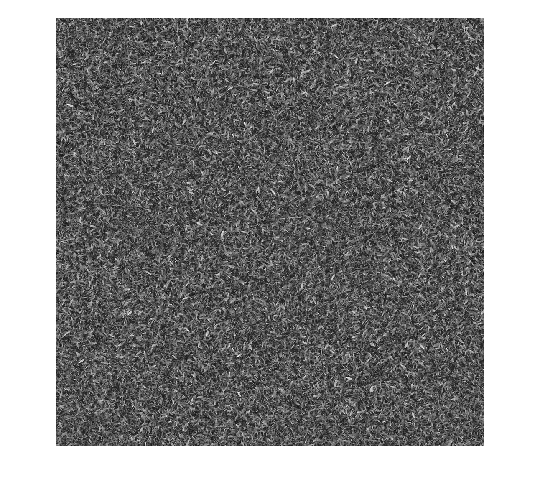

imshow(stone_displace);


% Factor displacement maps

    %normalize
grass_displace = grass_displace .* (0.5 / mean(mean(grass_displace)));
stone_displace = stone_displace .* (0.5 / mean(mean(stone_displace)));

mean(mean(grass_displace))

ans = 0.5000

mean(mean(stone_displace))

ans = 0.5000

%grass_displace = grass_displace + gauss_combined;
%stone_displace = stone_displace + (1 - gauss_combined);

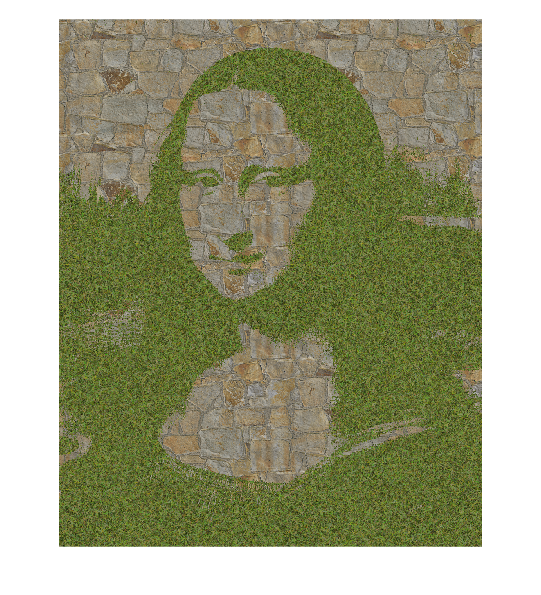

% Loop
result_image = zeros(size(image,1), size(image,2), 3);
for row = 1:1:size(image,1)
    for column = 1:1:size(image,2)

        if thresh(row, column) == 0
            color = getpixel(stone_diffuse, row, column);
        else
            color = getpixel(grass_diffuse, row, column);
        end
        
        result_image(row, column, :) = color(:);
    end
end

imshow(result_image)

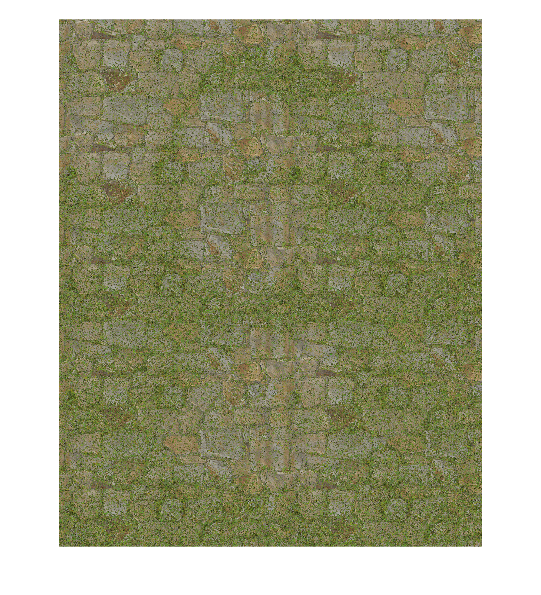

% height loop
result_image = zeros(size(image,1), size(image,2), 3);
for row = 1:1:size(image,1)
    for column = 1:1:size(image,2)


        %stone_height = getpixel(stone_displace, row, column) + 0.5*(1 - gauss_combined(row, column));
        %grass_height = getpixel(grass_displace, row, column) + 0.5*gauss_combined(row, column);

        stone_height = getpixel(stone_displace, row, column);
        grass_height = getpixel(grass_displace, row, column);

        stone_height = stone_height + 0.1 * (1 - gauss_combined(row, column));
        grass_height = grass_height + 0.1 * (gauss_combined(row, column));


        if grass_height >= stone_height
            color = getpixel(grass_diffuse, row, column);
        else
            color = getpixel(stone_diffuse, row, column);
        end
        
        result_image(row, column, :) = color(:);
    end
end

imshow(result_image)